Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi

Dipartimento di Ingegneria Industriale

Universita` degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Add path for the library

addpath('../matlab');
addpath('../matlab/DAE');
addpath('../matlab/DAE_lib');

#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

mass    = 1;
gravity = 9.81;
ell     = 1;
Iz      = 1;
DAE     = BiralDAE1( mass, gravity, ell, Iz );

#### Initialize the solver class

solver = DAE3TaylorSolver();
solver.setDAE( DAE );

#### Initialize the range where solution is computed and initial conditions

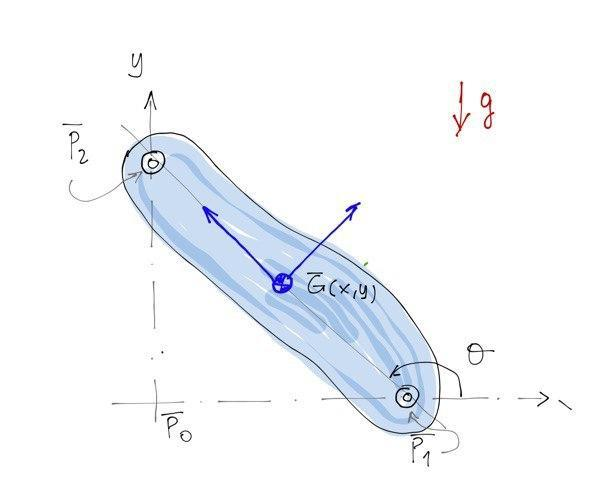

T     = 10;
DT    = 0.1;
theta = pi-pi/4;
x     = -ell*sin(theta)/2;
y     = ell*cos(theta)/2;
% x, y, theta
p0    = [ x, y, theta ];
omega = 0.1;
u     = -ell*cos(theta)*omega/2;
v     = -ell*sin(theta)*omega/2;
% u, v, omega
v0    = [ u, v, omega ];

#### Advance the DAE (using not stabilized index-1 DAE)

tt  = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
[p, v, lambda ] = solver.advance_simple( tt,  p0, v0 );
[p1,v1,lambda1] = solver.advance_simple( tt1, p0, v0 );
[p2,v2,lambda2] = solver.advance_simple( tt2, p0, v0 );

#### Position of center of gravity

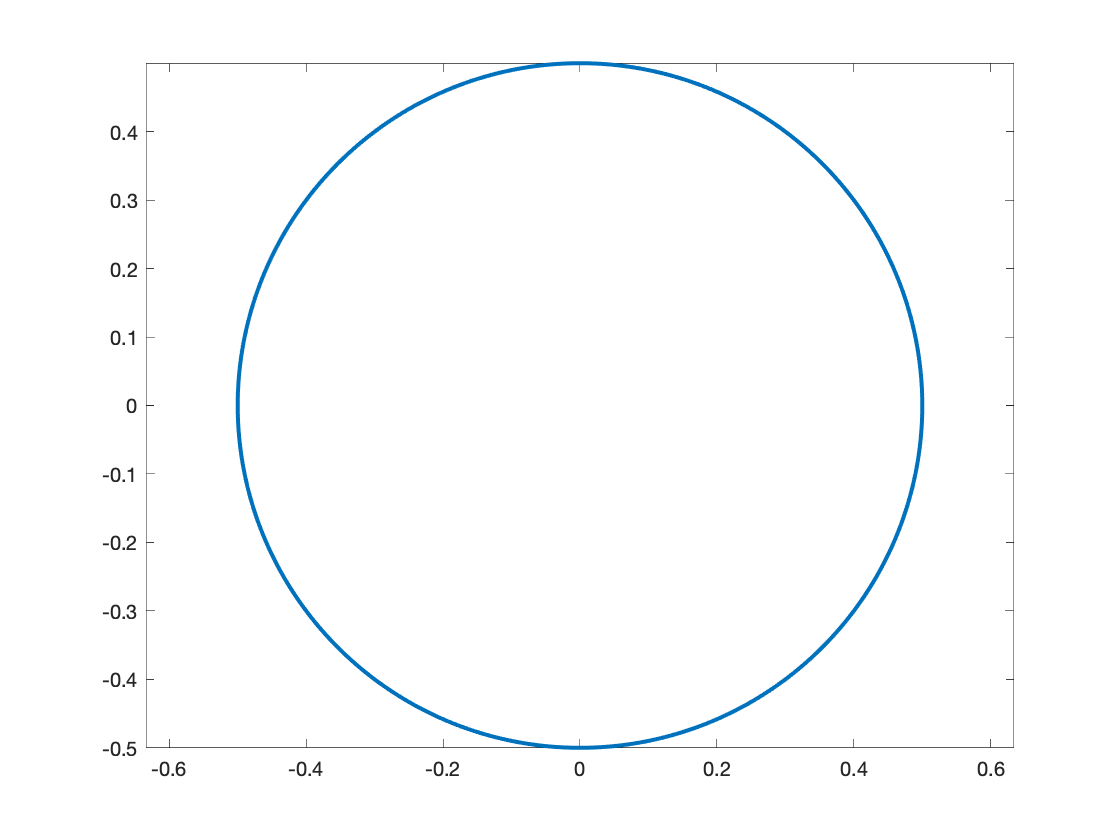

thg = pi:0.01:4*pi;
xg  = -ell*sin(thg)/2;
yg  = ell*cos(thg)/2;
plot(xg,yg,'LineWidth',2);
axis equal;

#### plot solution

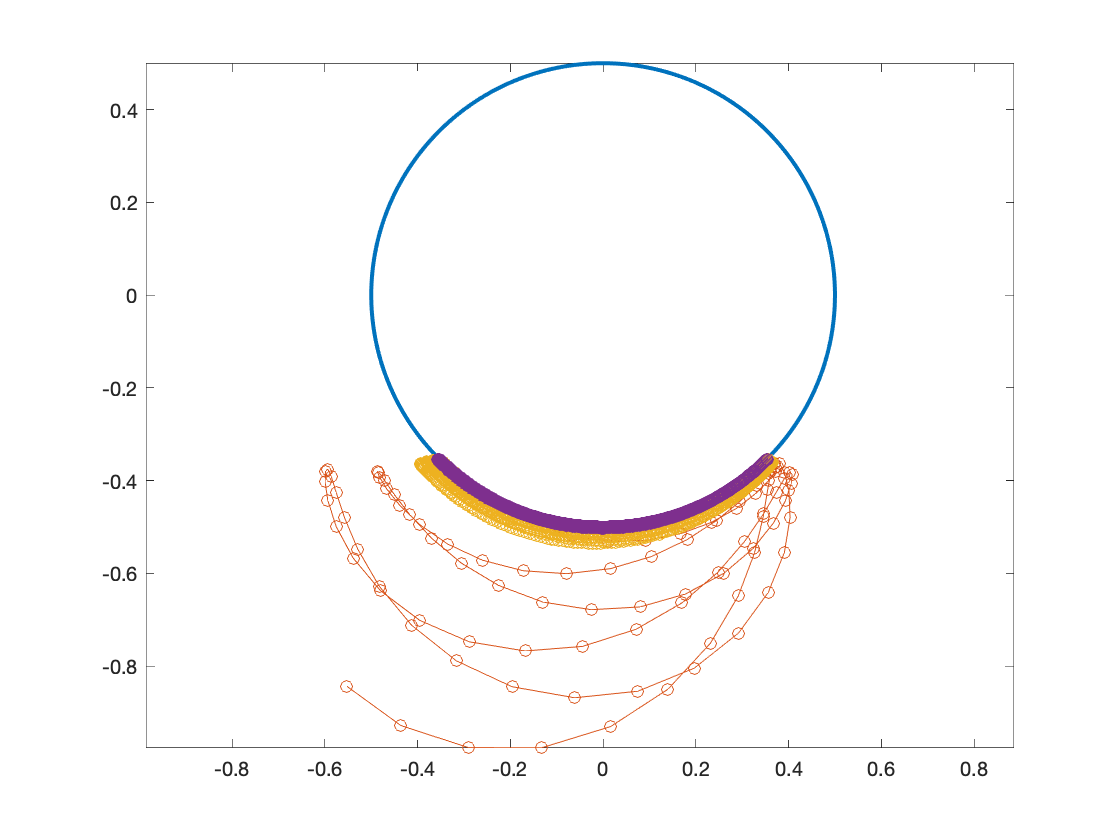

plot( xg, yg, 'Linewidth', 2);
hold on;
plot( p(1,:),  p(2,:),  'o-', 'Linewidth', 0.2);
plot( p1(1,:), p1(2,:), 'o-', 'Linewidth', 0.2);
plot( p2(1,:), p2(2,:), 'o-', 'Linewidth', 0.2);
hold off
axis equal

#### Advance the DAE (using stabilized index-1 DAE)

choose the parameters

eta   = 0.5;
omega = 1;

advance

tt  = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
[p, v, lambda ] = solver.advance_Baumgarte( tt,  p0, v0, eta, omega );
[p1,v1,lambda1] = solver.advance_Baumgarte( tt1, p0, v0, eta, omega );
[p2,v2,lambda2] = solver.advance_Baumgarte( tt2, p0, v0, eta, omega );

#### plot solution

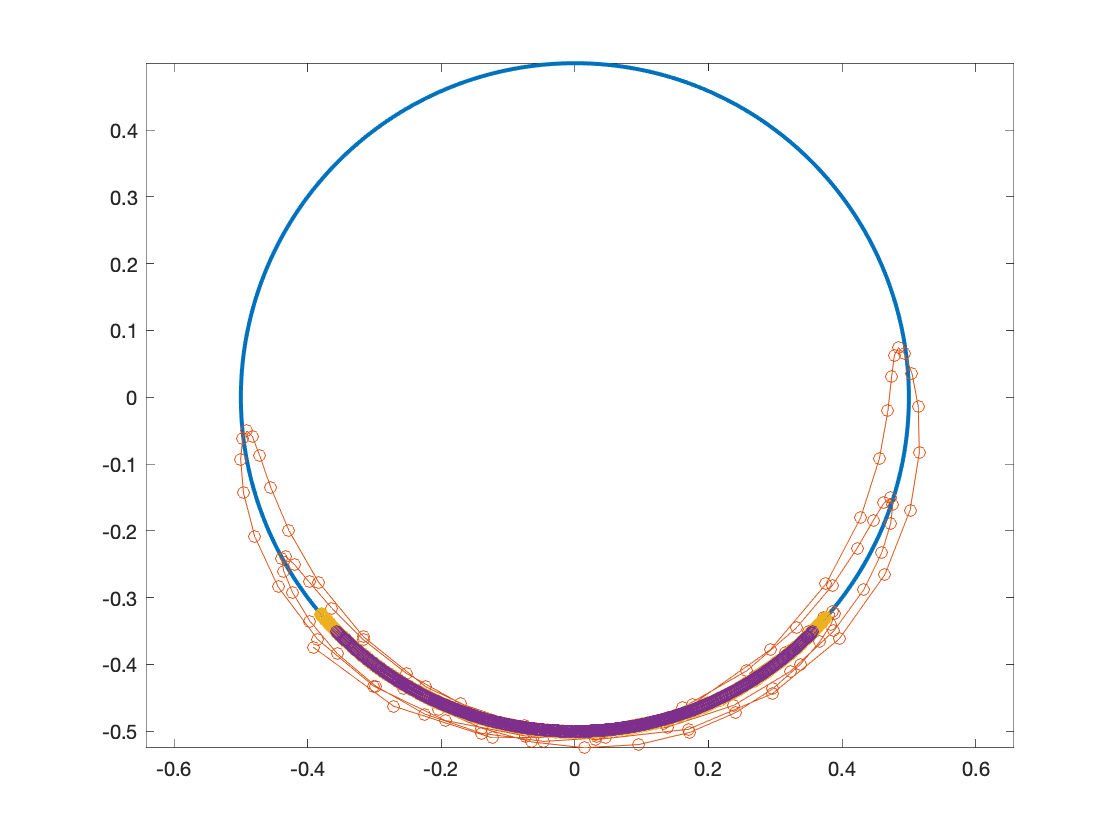

plot( xg, yg, 'Linewidth', 2);
hold on;
plot( p(1,:),  p(2,:),  'o-', 'Linewidth', 0.2);
plot( p1(1,:), p1(2,:), 'o-', 'Linewidth', 0.2);
plot( p2(1,:), p2(2,:), 'o-', 'Linewidth', 0.2);
hold off
axis equal